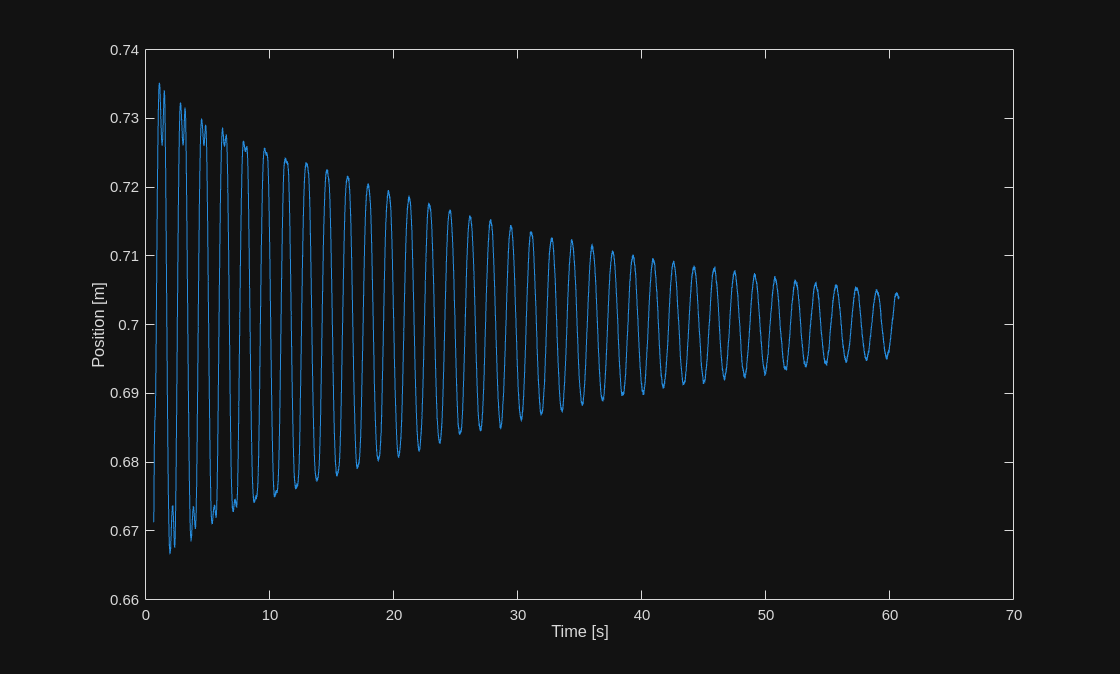

clc; clear; close all;
load test_trj1_copy_NO_SHAPER.mat

time = time(665:end);
joint_position = joint_position(665:end);
plot(time, joint_position)
xlabel("Time [s]")
ylabel("Position [m]")

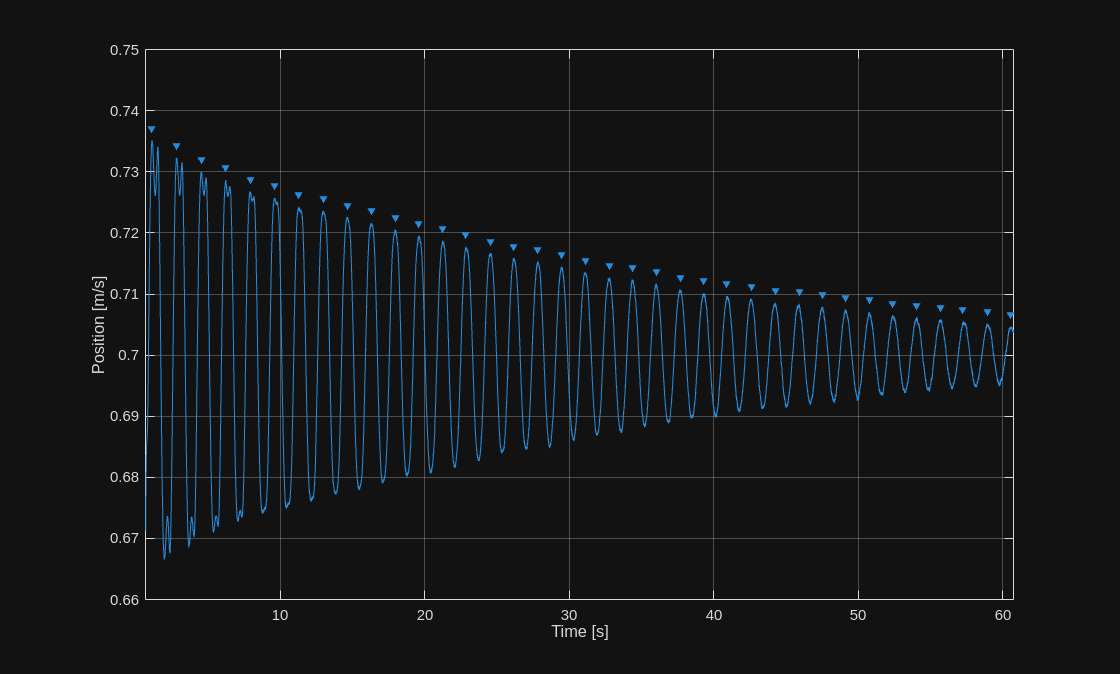

[pks,locs] = findpeaks(joint_position,time, MinPeakDistance=1);
findpeaks(joint_position,time, MinPeakDistance=1)
xlabel("Time [s]")
ylabel("Position [m/s]")

xi = 1/sqrt( 1+( (2*pi) / (log (locs(1)/locs(2)) ))^2)

xi = 0.1475

res = [];
for i=1:length(locs)-1
    res = [res;2*pi/(locs(i+1)-locs(i))];

end
omega_d=mean(res)

omega_d = 3.8061

res = [];
for i=1:length(locs)-1
    res = [res;1/sqrt( 1+( (2*pi) / (log (locs(i)/locs(i+1)) ))^2)];

end
xi = mean(res)

xi = 0.0176